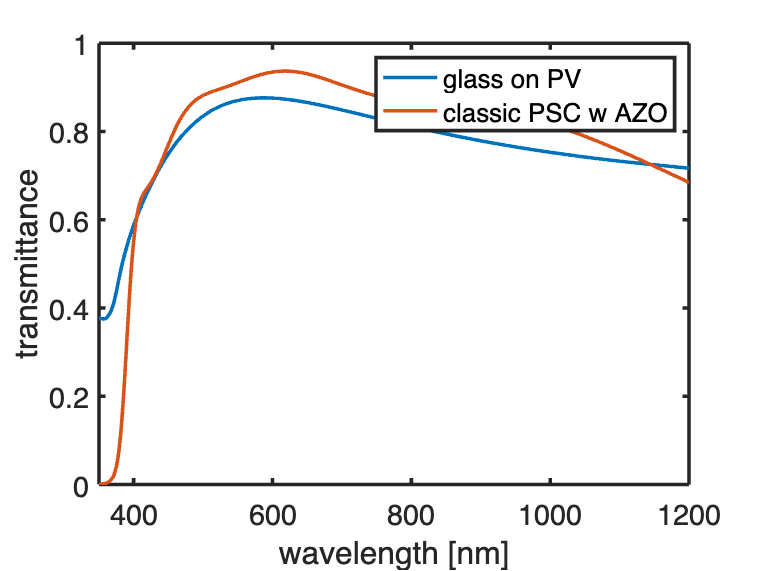

%% SCRIPT FOR TESTING LIGHT PROPAGATION THROUGH BRAGG WITH GLASS
% -------------------------------------------------------------------------
%% GENERAL INPUT DATA
% -------------------------------------------------------------------------
lam = linspace(350, 1200, 851);
Bragg = repmat(["SiO2", "TiO2"],1,4);
matPSC = [Bragg,"gls",fliplr(Bragg)];
dBragg =  [110.18, 25.18, 27.09, 50, 22.83, 33.65, 44.78, 12.68]; % SiO2/TiO2 x4
dgls = 2e6; 
dair = 2e6; dEVA = 2e6; dAZO = 5; dARC = 61.8;
incoh = 1e3; % incoherent layer is 1000nm thickness
theta = 0;
% -------------------------------------------------------------------------
% PSC as is in air
% -------------------------------------------------------------------------
materials = ["air",matPSC,"air"];
dPSC = [dBragg, dgls, fliplr(dBragg)];
stack = set_stack( materials, dPSC, lam, theta, incoh );
[~, T_PSC_air, R_PSC_air] = ATR1D( stack );
% -------------------------------------------------------------------------
% glass on PV
% -------------------------------------------------------------------------
materials = ["air","gls","air","const=2.4254","mSi"];
d = [dgls,dair,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, T_gls_air_PV, R_gls_air_PV] = ATR1D( stack );
% -------------------------------------------------------------------------
% PSC with AZO and air gap on PV
% -------------------------------------------------------------------------
materials = ["air",matPSC,"AZO","air","const=2.4254","mSi"];
d = [dPSC,dAZO,dair,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, T_PSC_AZO_air_PV, R_PSC_AZO_air_PV] = ATR1D( stack );
% -------------------------------------------------------------------------
% PSC with AZO and EVA on PV
% -------------------------------------------------------------------------
materials = ["air",matPSC,"AZO","EVA","const=2.4254","mSi"];
d = [dPSC,dAZO,dEVA,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, T_PSC_AZO_EVA_PV, R_PSC_AZO_EVA_PV] = ATR1D( stack );
% -------------------------------------------------------------------------
% PSC no AZO and air gap on PV
% -------------------------------------------------------------------------
materials = ["air",matPSC,"air","const=2.4254","mSi"];
d = [dPSC,dair,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, T_PSC_air_PV, R_PSC_air_PV] = ATR1D( stack );
% -------------------------------------------------------------------------
% DSM glass EVA PV
% -------------------------------------------------------------------------
materials = ["gls","EVA","const=2.4254","mSi"];
d = [dEVA,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, T_DSM_EVA_PV, R_DSM_EVA_PV] = ATR1D( stack );
%
load("DSM.mat");
DSM_lam = interp1( DSM(:,1), DSM(:,2), lam, 'spline' )';
T_DSM_EVA_PV = T_DSM_EVA_PV.sp.*DSM_lam;                         
% -------------------------------------------------------------------------
% PLOTTING RESULTS
% -------------------------------------------------------------------------
% Fraunhofer data
figure();
plot(lam,T_gls_air_PV.sp,lam,T_PSC_AZO_air_PV.sp);
xlabel('wavelength [nm]'); ylabel('transmittance');
xlim([lam(1) lam(end)]); ylim([0 1]);
legend('glass on PV','classic PSC w AZO')

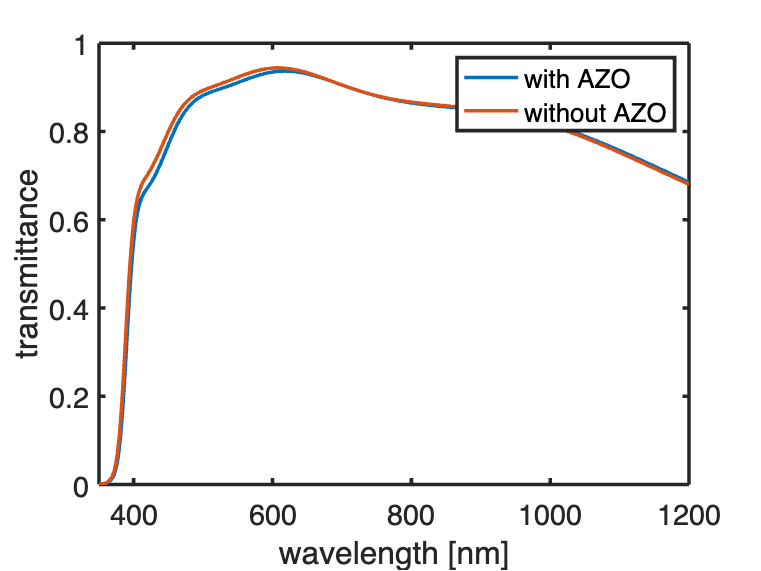

% Impact of the AZO
figure();
plot(lam,T_PSC_AZO_air_PV.sp,lam,T_PSC_air_PV.sp);
xlabel('wavelength [nm]'); ylabel('transmittance');
xlim([lam(1) lam(end)]); ylim([0 1]);
legend('with AZO','without AZO')

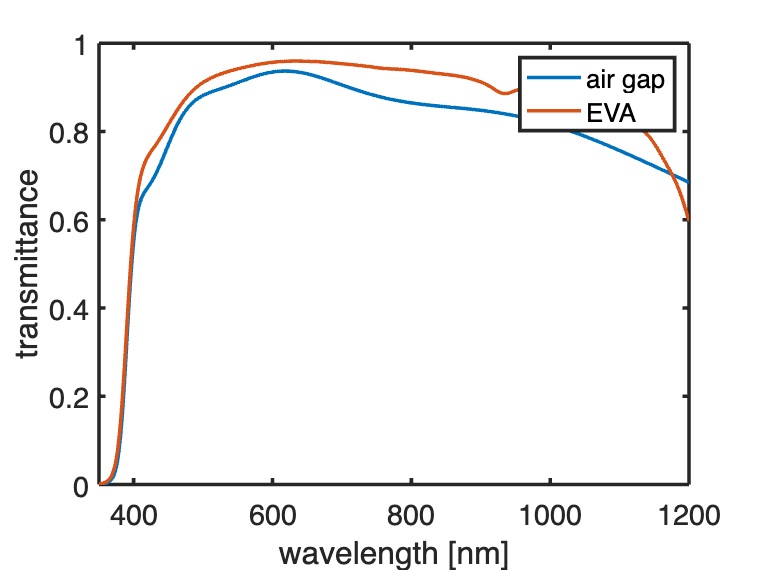

% Impact of EVA
figure();
plot(lam,T_PSC_AZO_air_PV.sp,lam,T_PSC_AZO_EVA_PV.sp);
xlabel('wavelength [nm]'); ylabel('transmittance');
xlim([lam(1) lam(end)]); ylim([0 1]);
legend('air gap','EVA')

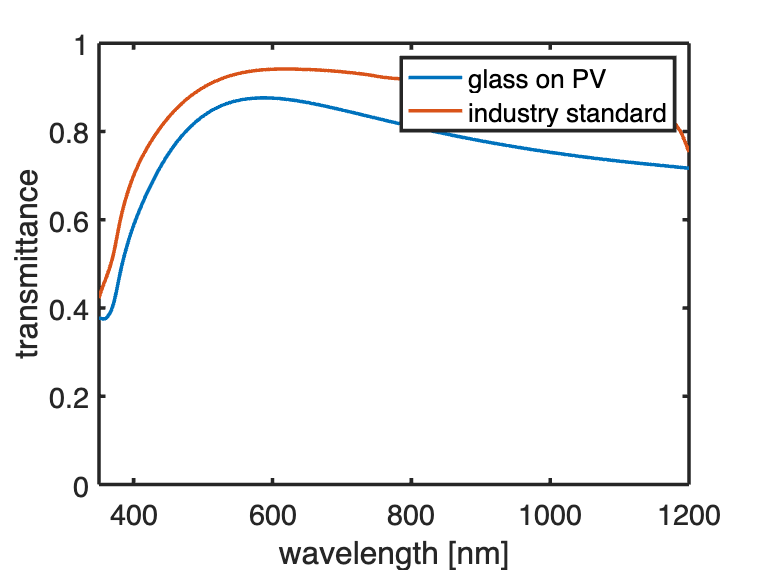

% baselines
figure();
plot(lam,T_gls_air_PV.sp,lam,T_DSM_EVA_PV);
xlabel('wavelength [nm]'); ylabel('transmittance');
xlim([lam(1) lam(end)]); ylim([0 1]);
legend('glass on PV','industry standard')

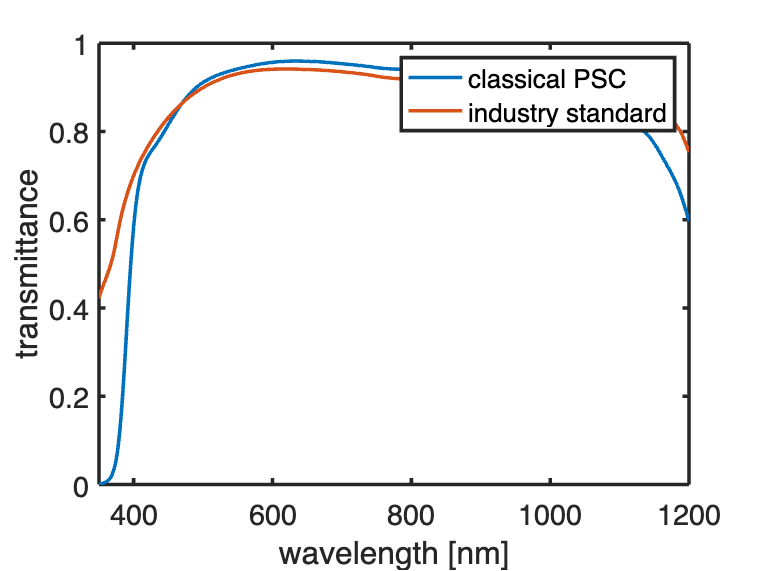

% relevant comparison
figure();
plot(lam,T_PSC_AZO_EVA_PV.sp,lam,T_DSM_EVA_PV);
xlabel('wavelength [nm]'); ylabel('transmittance');
xlim([lam(1) lam(end)]); ylim([0 1]);
legend('classical PSC','industry standard')

% electric stuff
IV_gls_air_PV = get_electric(lam, T_gls_air_PV.sp);
IV_PSC_AZO_air_PV = get_electric(lam, T_PSC_AZO_air_PV.sp);
IV_PSC_air_PV = get_electric(lam, T_PSC_air_PV.sp);
IV_PSC_AZO_EVA_PV = get_electric(lam, T_PSC_AZO_EVA_PV.sp);
IV_DSM_EVA_PV = get_electric(lam, T_DSM_EVA_PV);
%
headers = {'wavelength [nm]',...
           'T_gls_air_PV',...
           'T_PSC_AZO_air_PV',...
           'T_PSC_air_PV',...
           'T_PSC_AZO_EVA_PV',...
           'T_DSM_EVA_PV'};
data = [headers;
    [num2cell(lam'),...
     num2cell(T_gls_air_PV.sp),...
     num2cell(T_PSC_AZO_air_PV.sp),...
     num2cell(T_PSC_air_PV.sp),...
     num2cell(T_PSC_AZO_EVA_PV.sp),...
     num2cell(T_DSM_EVA_PV)]];
writecell(data,'CSF1.21.xlsx','Sheet','T');
%
headers = {'gls_air_PV',...
           'PSC_AZO_air_PV',...
           'PSC_air_PV',...
           'PSC_AZO_EVA_PV',...
           'DSM_EVA_PV'};
data = [headers;
    [num2cell(IV_gls_air_PV.jsc),...
     num2cell(IV_PSC_AZO_air_PV.jsc),...
     num2cell(IV_PSC_air_PV.jsc),...
     num2cell(IV_PSC_AZO_EVA_PV.jsc),...
     num2cell(IV_DSM_EVA_PV.jsc)]];
writecell(data,'CSF1.21.xlsx','Sheet','Jsc');